% cleaning environment
clc
clear all

% importing data
df1 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=999031192&single=true&output=csv")

df1 = 1×5 table
          description          value     uom      uncertainty       tool    
    _______________________    _____    ______    ___________    ___________

    {'lunghezza fenditura'}    1.85     {'cm'}       0.005       {'calibro'}


df2 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=0&single=true&output=csv")

df2 = 10×15 table
    configuration    measure_id    x_proiettore    x_oggetto    x_lente    x_schermo_inf    x_schermo_sup    x_uncertainty     x_uom       x_tool      l_img_inf    l_img_sup    l_uncertainty     l_uom       l_tool   
    _____________    __________    ____________    _________    _______    _____________    _____________    _____________    _______    __________    _________    _________    _____________    _______    ___________

          1          {'C1M1' }       

df3 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=905714583&single=true&output=csv")

df3 = 1×13 table
    configuration    measure_id    x_proiettore    x_oggetto    x_lente    x_schermo    x_uncertainty     x_uom       x_tool      l_img    l_uncertainty     l_uom       l_tool   
    _____________    __________    ____________    _________    _______    _________    _____________    _______    __________    _____    _____________    _______    ___________

          2           {'C2M1'}         4.6           10.1        31.15       50.4           0.05         {'CMT'}    {'regolo'}    1.85         0.005        {'CMT'}    {'calibro'}


df4 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=245849005&single=true&output=csv")

df4 = 11×13 table
    configuration    measure_id    x_oggetto    x_schermo    x_medio    x_lente_1    x_lente_2    x_uncertainty      uom         tool        s       d      delta
    _____________    __________    _________    _________    _______    _________    _________    _____________    _______    __________    ____    ____    _____

          2          {'C2M1' }       10.1           54        32.05       24.15         38.9          0.05         {'CMT'}    {'regolo'}     7.9    6.85    1.05 
          2          {'C2M2' }       10.1         54.

% assegno lunghezza oggetto
o = df1.value

o = 1.8500

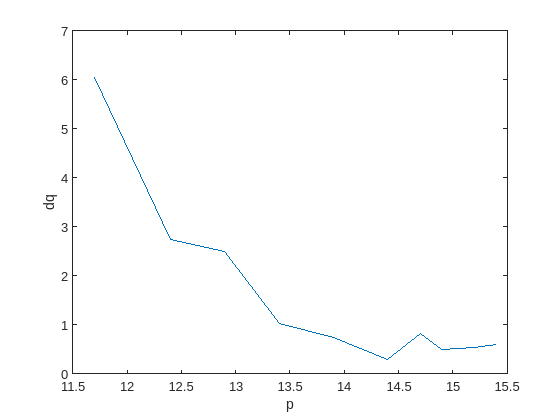

% calcolo p: distanza oggetto-lente
p = abs(df2.x_lente-df2.x_oggetto);
dp = df2.x_uncertainty*2;
df2.p = p;
df2.dp = dp;

% calcolo q: distanza lente-immagine
q_inf = abs(df2.x_lente - df2.x_schermo_inf);
q_sup = abs(df2.x_lente - df2.x_schermo_sup);
q = (q_inf+q_sup)/2;
% l'incertezza sulla posizione dello schermo è data dal semi-intervallo entro il quale l'immagine appare ugualmente nitida
dq = abs(df2.x_schermo_sup - df2.x_schermo_inf)/2;
df2.q = q;
df2.dq = dq;

plot(p,dq)
xlabel("p")
ylabel("dq")

noto che l'ampiezza del semi intervallo diminuisce all'aumentare di p distanza oggetto lente

% esporto tabella per relazione (converto in testo e approssimo)
[tp, tdp] = signum2str(p,dp);
[tq, tdq] = signum2str(q,dq);
pq = array2table([tp, tdp, tq, tdq],"VariableNames",{'p','$\delta p$','q','$\delta q$'})

pq = 10×4 table
      p       $\delta p$      q       $\delta q$
    ______    __________    ______    __________

    "11.7"      "0.1"       "51"        "6"     
    "12.4"      "0.1"       "41"        "3"     
    "12.9"      "0.1"       "39"        "3"     
    "13.4"      "0.1"       "34"        "1"     
    "13.9"      "0.1"       "32.0"      "0.8"   
    "14.4"      "0.1"       "29.5"      "0.3"   
    "14.7"      "0.1"       "28.9"      "0.8"   
    "14.9"      "0.1"       "28.3"      "0.5"   
    "15.2"      "0.1"       "27.1"      "0.6"   
    "15.4"      "0.1"       "26.7"      "0.6"   


writetable(pq,"../data/pq.csv")

## Determinazione diretta della distanza focale

% calcolo f mediante formula (2) scheda
f = (p.*q)./(p+q);

% propagazione errore su f
df = sqrt((((q./(p+q)).^2).*dp).^2 + (((p./(p+q)).^2).*dq).^2);

% esporto tabella con f e incertezze
[tf, tdf] = signum2str(f,df);
table = array2table([tf tdf],"VariableNames",{'f','$\delta f$'})

table = 10×2 table
      f       $\delta f$
    ______    __________

    "9.5"       "0.2"   
    "9.5"       "0.2"   
    "9.7"       "0.2"   
    "9.64"      "0.1"   
    "9.70"      "0.08"  
    "9.68"      "0.06"  
    "9.7"       "0.1"   
    "9.76"      "0.07"  
    "9.74"      "0.08"  
    "9.77"      "0.09"  


writetable(table,"../data/fdirect.csv")

% media di f
fm = mean(f);
dfm = mean(df);
[fm, dfm] = siground(fm,dfm)

fm = 9.7000

dfm = 0.1000

[tfm, tdfm] = signum2str(fm,dfm)

tfm = '9.7'

tdfm = '0.1'

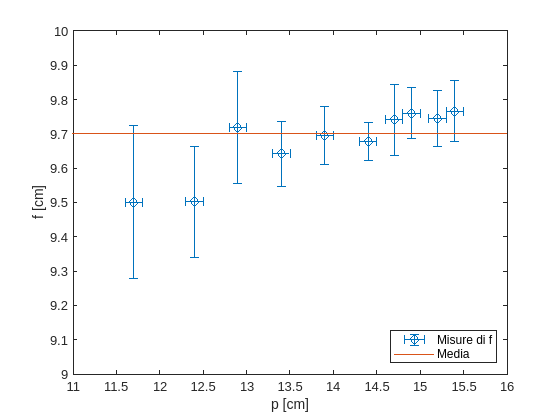

% rappresento f con le incertezze
fig=figure;
errorbar(p,f,df,df,dp,dp,'o')
hold on
plot(10:16,repelem(fm,length(10:16)),'Color','#D95319')
hold off
ylim([9 10])
xlim([11 16])
xlabel("p [cm]")
ylabel("f [cm]")
legend("Misure di f","Media",'Location','southeast')
saveas(fig,"../img/pf.png")

## Significatività della correlazione lineare: indice di Bravais-Pearson

linearizzo l'equazione 

verificare la propagazione degli errori del reciproco. Mi sembra strano si riduca così.

% linearizzo equazione
y  = 1./q;
dy = usiground(dq./q.^2);
x  = 1./p;
dx = usiground(dp./p.^2);

% converto in testo per esportare tabella con corretto numero di cifre
% significative
[tx, tdx] = signum2str(x,dx);
[ty, tdy] = signum2str(y,dy);
linearize_text_data = array2table([tx tdx ty tdy],"VariableNames",["x","dx","y","dy"])

linearize_text_data = 10×4 table
       x           dx          y           dy   
    ________    ________    ________    ________

    "0.0855"    "0.0007"    "0.020"     "0.002" 
    "0.0806"    "0.0007"    "0.025"     "0.002" 
    "0.0775"    "0.0006"    "0.025"     "0.002" 
    "0.0746"    "0.0006"    "0.0291"    "0.0009"
    "0.0719"    "0.0005"    "0.0312"    "0.0007"
    "0.0694"    "0.0005"    "0.0339"    "0.0003"
    "0.0680"    "0.0005"    "0.035"     "0.001" 
    "0.0671"    "0.0005"    "0.0353"    "0.0006"
    "0.0658"    "0.0004"    "0.0368"    "0.0007"
    "0.0649"    "0.0004"    "0.0375"    "0.0008"


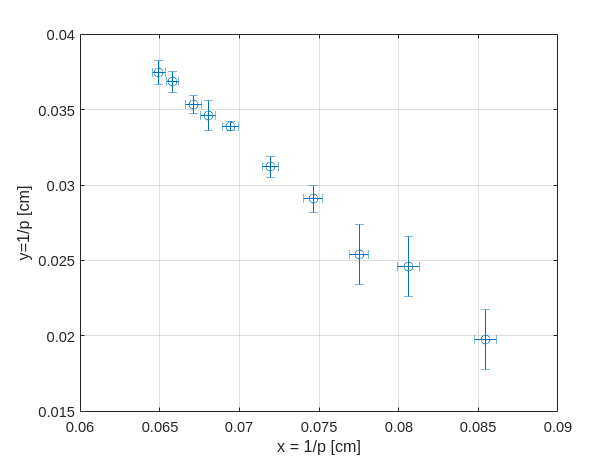

% esporto in csv
writetable(linearize_text_data,"../data/linearized.csv")

% plot
figure;
errorbar(x,y,dy,dy,dx,dx,'o')
xlabel("x = 1/p [cm]")
ylabel("y=1/p [cm]")
grid on

% coefficiente di bravais pearson

% funzione personale
r1 = abs(bravpear(x,y))

r1 = 0.9966

% funzione matlab
%[r2, pval] = corr(x,y)
%pval < 0.01

in questo modo ho comunque verificato che la funzione corr() torna esattamente il valore voluto ovvero quello della funzione bravpear() che corrisponde alla formula per calcolare bravais pearson.

A seguito del calcolo del coefficiente di Bravais-Pearson e del p-value (probabilità che un'insieme di dati presenti una forma di quel tipo senza rapporti di causa effetto) si conclude che le grandezze x e y prsentano una correlazione lineare altamente significativa in quanto pval = 6e-10 << 0.01 = 1%

## Best-fit: metodo dei minimi quadrati

% fare: bestfit
[a, sigma_a, b, sigma_b] = best_fit_mmq(x,y,true)

a = 0.0930

sigma_a = 0.0020

b = -0.8600

sigma_b = 0.0300

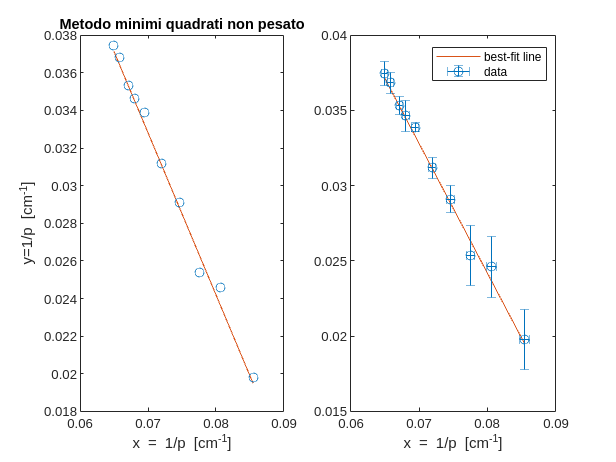

yfit1 = a+b.*x;

figure;
subplot(1,2,1)
plot(x,yfit1,'Color','#D95319')
title("Metodo minimi quadrati non pesato")
%sprintf("best-fit line: y=(%.3f +- %.3f) + (%.2f+- %.2f) x",a,sigma_a,b,sigma_b)
%sprintf("best-fit line: y = %.3f %.2f x",a,b)
hold on
scatter(x,y,'MarkerEdgeColor','#0072BD')
hold off
xlabel("x = 1/p [cm^{-1}]")
ylabel("y=1/p [cm^{-1}]")
subplot(1,2,2)
plot(x,yfit1,'Color','#D95319')
hold on
errorbar(x,y,dy,dy,dx,dx,'o','Color','#0072BD')
hold off
xlabel("x = 1/p [cm^{-1}]")
legend("best-fit line","data")

osserve che gli errori sulla y non sono costanti quindi è necessario fare il best fit pesato.

[a2, sigma_a2, b2, sigma_b2] = weighted_best_fit_mmq(x,y,dy,false)

a2 = 0.0937

sigma_a2 = 0.0045

b2 = -0.8638

sigma_b2 = 0.0654

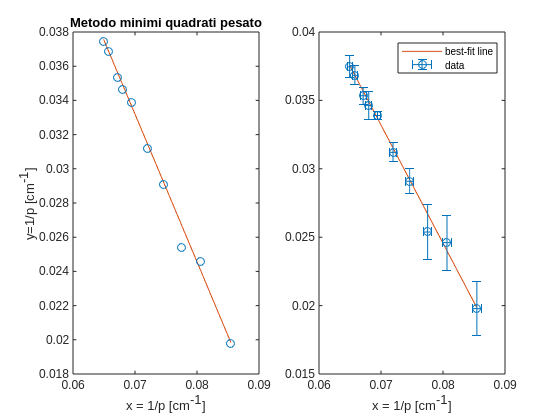

yfit2 = a2+b2.*x;
figure;
subplot(1,2,1)
plot(x,yfit2,'Color','#D95319')
title("Metodo minimi quadrati pesato")
hold on
scatter(x,y,'MarkerEdgeColor','#0072BD')
hold off
xlabel("x = 1/p [cm^{-1}]")
ylabel("y=1/p [cm^{-1}]")
subplot(1,2,2)
plot(x,yfit2,'Color','#D95319')
hold on
errorbar(x,y,dy,dy,dx,dx,'o','Color','#0072BD')
hold off
xlabel("x = 1/p [cm^{-1}]")
legend("best-fit line","data")

% round
[ta2, tsigma_a2] = signum2str(a2,sigma_a2)

ta2 = '0.094'

tsigma_a2 = '0.005'

[tb2, tsigma_b2] = signum2str(b2,sigma_b2)

tb2 = '-0.86'

tsigma_b2 = '0.07'

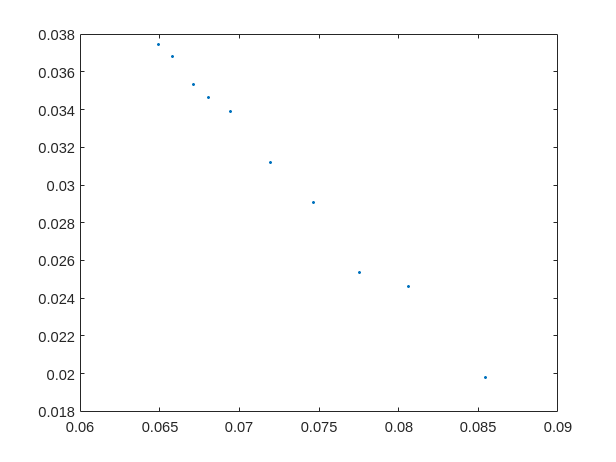

% test best-fit integrato in matlab
figure
plot(x,y,'.');

ft = fittype('poly1');

'fittype' requires Curve Fitting Toolbox.

w = 1./dy.^2;
cf = fit(x,y,ft,'Weight',w);
hold on
plot(cf,'fit',0.95);

% chi-quadro per un fit (sia pesato che non pesato)
chi1=fitchisquarered(y,dy,yfit1,2)

chi1 = 0.6705

chi2=fitchisquarered(y,dy,yfit2,2)

chi2 = 0.2169


% calcolare incertezza fmmq
fmmq = 1/a;
dfmmq = sigma_a./a.^2;

verificare che l'incertezza nel reciproco si propaga in questo modo

[fmmq, dfmmq] = siground(fmmq, dfmmq)

fmmq = 10.8000

dfmmq = 0.2000

fmmq2 = 1./a2;
dfmmq2 = sigma_a2./a2.^2;
[fmmq2, dfmmq2] = siground(fmmq2, dfmmq2)

fmmq2 = 10.7000

dfmmq2 = 0.5000

## Ingrandimento 

l_oggetto = df1.value

l_oggetto = 1.8500

dlo = df1.uncertainty

dlo = 0.0050

l_immagine = (df2.l_img_sup + df2.l_img_inf)./2

l_immagine =     7.1050
    5.6600
    5.5800
    4.5425
    4.1525
    3.4375
    3.5775
    3.4725
    3.5725
    3.1425


assumo come incertezza sulla lunghezza dell'immagine il semi intervallo

dli = abs(df2.l_img_sup - df2.l_img_inf)./2;

% calcolo m come rapporto i/o
m1 = l_immagine./l_oggetto;
dm1 = sqrt((dli./l_oggetto).^2 + ((l_immagine.*dlo)./(l_oggetto.^2)));
[m1, dm1] = siground(m1,dm1);

tlinf = signum2str(df2.l_img_inf,df2.l_uncertainty);
tlsup = signum2str(df2.l_img_sup,df2.l_uncertainty);

% approssimo ed esporto tabella
[tm1, tdm1] = signum2str(m1,dm1);
[tli, tdli] = signum2str(l_immagine,dli);
table = [tlinf tlsup tli, tdli, tm1, tdm1];
table = array2table(table,"VariableNames",{'$l_{inf} \; [cm]$','$l_{sup} \; [cm]$','i [cm]','$\delta i \; [cm]$','$m_1$','$\delta m_1$'});
% add measure id
table.measure_id = df2.measure_id;
% riordino colonne
newColumnOrder = {'measure_id', '$l_{inf} \; [cm]$','$l_{sup} \; [cm]$','i [cm]','$\delta i \; [cm]$','$m_1$','$\delta m_1$'};
table = table(:,newColumnOrder);
% rinomino colonna
table.Properties.VariableNames{'measure_id'} = 'Measure ID';
writetable(table,"../data/mio.csv")

% preview
table

table = 10×7 table
    Measure ID    $l_{inf} \; [cm]$    $l_{sup} \; [cm]$    i [cm]    $\delta i \; [cm]$    $m_1$     $\delta m_1$
    __________    _________________    _________________    ______    __________________    ______    ____________

    {'C1M1' }          "6.360"              "7.850"         "7.1"           "0.7"           "3.8"        "0.4"    
    {'C1M2' }          "5.090"              "6.230"         "5.7"           "0.6"           "3.1"        "0.3"    
    {'C1M3' }          "5.065"              "6.095"         "5.6"           "0.5"           "3.0"        "0.3"    
    {'C1M4' }          "4.235"              "4.850"         "4.5"           "0.3"           "2.5"        "0.2"    
    {'C1M5' }          "3.985"              "4.320" 


% calcolo m come rapporto q/p
m2 = q./p;
dm2 = sqrt((dq./p).^2 + ((q.*dp)./(p.^2)));
[m2, dm2] = siground(m2,dm2);

% approssimo ed esporto
[tm2, tdm2] = signum2str(m2,dm2);

table = [tm1, tdm1, tm2, tdm2];
table = array2table(table,"VariableNames",{'$m_1$','$\delta m_1$','$m_2$','$\delta m_2$'});
% add measure id
table.measure_id = df2.measure_id;
% riordino colonne
newColumnOrder = {'measure_id', '$m_1$','$\delta m_1$','$m_2$','$\delta m_2$'};
table = table(:,newColumnOrder);
% rinomino colonna
table.Properties.VariableNames{'measure_id'} = 'Measure ID';
% esporto
writetable(table,"../data/ms.csv")

% preview
table

table = 10×5 table
    Measure ID    $m_1$     $\delta m_1$    $m_2$    $\delta m_2$
    __________    ______    ____________    _____    ____________

    {'C1M1' }     "3.8"        "0.4"        "4.3"       "0.6"    
    {'C1M2' }     "3.1"        "0.3"        "3.3"       "0.3"    
    {'C1M3' }     "3.0"        "0.3"        "3.1"       "0.2"    
    {'C1M4' }     "2.5"        "0.2"        "2.6"       "0.2"    
    {'C1M5' }     "2.2"        "0.1"        "2.3"       "0.1"    
    {'C1M6' }     "1.9"        "0.1"        "2.0"       "0.1"    
    {'C1M7' }     "1.9"        "0.2"        "2.0"       "0.1"    
    {'C1M8' }     "1.88"       "0.08"       "1.9"       "0.1"    
    {'C1M9' }     "1.9"        "0.2"        "1.8"       "0.1"    
    {'C1M10'}     "1.7"        "0.1"        "1.7"       "0.1"    



% differenze
[t_diff_m, t_error_diffm] = signum2str(abs(m2-m1),dm1+dm2);

% costruisco dataset per plot
ms = [m1, m2];
dms = [dm1, dm2];



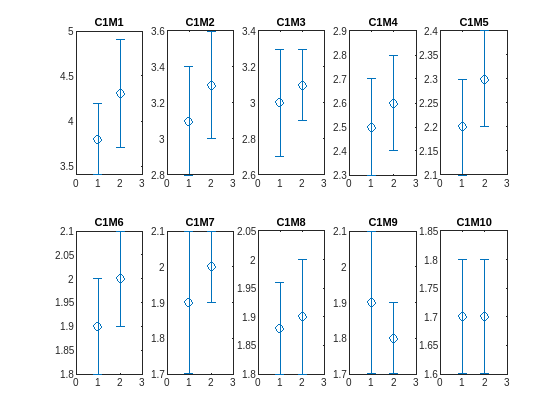


fig=figure;
for i=1:10
    subplot(2,5,i)
    errorbar(1:2,ms(i,:)',dms(i,:)',dms(i,:)','o')
    title(sprintf("C1M%i",i))
    xlim([0 3])
end

saveas(fig,"../img/ms_r.png")

## Metodo di Bessel

df3

df3 = 1×13 table
    configuration    measure_id    x_proiettore    x_oggetto    x_lente    x_schermo    x_uncertainty     x_uom       x_tool      l_img    l_uncertainty     l_uom       l_tool   
    _____________    __________    ____________    _________    _______    _________    _____________    _______    __________    _____    _____________    _______    ___________

          2           {'C2M1'}         4.6           10.1        31.15       50.4           0.05         {'CMT'}    {'regolo'}    1.85         0.005        {'CMT'}    {'calibro'}


% distanza oggetto lente
ol = abs(df3.x_oggetto - df3.x_lente)

ol = 21.0500

% distanza lente schermo
ls = abs(df3.x_schermo - df3.x_lente)

ls = 19.2500

% errore sulle distanze
dd = df3.x_uncertainty*2

dd = 0.1000

% media delle distanze oggeto lente e lente schermo
olsm = mean([ol,ls])

olsm = 20.1500

dolsm = mean(dd)

dolsm = 0.1000

% determino f
fb = olsm/4

fb = 5.0375

% calcolo errore


## Valutazione errori sistematici

df4

df4 = 11×13 table
    configuration    measure_id    x_oggetto    x_schermo    x_medio    x_lente_1    x_lente_2    x_uncertainty      uom         tool        s       d      delta
    _____________    __________    _________    _________    _______    _________    _________    _____________    _______    __________    ____    ____    _____

          2          {'C2M1' }       10.1           54        32.05       24.15         38.9          0.05         {'CMT'}    {'regolo'}     7.9    6.85    1.05 
          2          {'C2M2' }       10.1         54.


% calcolo punto medio distanza oggetto schermo
pmos = (df4.x_oggetto + df4.x_schermo)/2;

% calcolo s e d 
% s: distanza pmos e prima posizione lente
% d: distanza pmos e seconda posizione lente
s = abs(df4.x_lente_1 - pmos);
d = abs(df4.x_lente_2 - pmos);

% propagazione errori
ds = 2.*df4.x_uncertainty;

% differenze
eta = s-d

eta =     1.0500
    1.2000
    0.8000
    1.1500
    1.3500
    1.9000
    1.0000
    0.8500
    1.1500
    0.6500


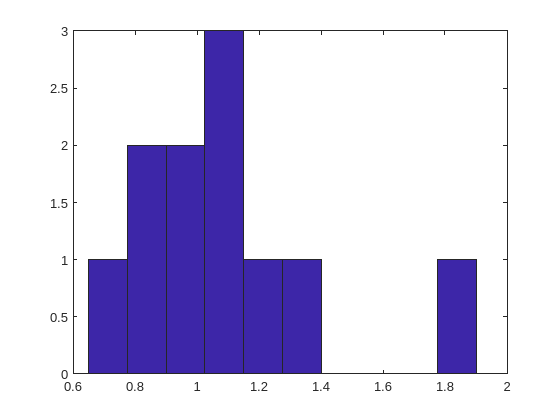


figure;
hist(eta)


[eta_best, sigma_eta] = siground(mean(eta),std(eta))

eta_best = 1.1000

sigma_eta = 0.3000


% converto in testo ed esporto tabella
[tpmos,tds] = signum2str(pmos,ds);
ts = signum2str(s,ds);
td = signum2str(d,ds);
teta = signum2str(eta,ds);

table=table(df4.measure_id,tpmos,ts,td,teta,'VariableNames',{'Measure ID','$x_m$','s','d','$\eta$'})

table = 11×5 table
    Measure ID    $x_m$       s         d      $\eta$
    __________    ______    ______    _____    ______

    {'C2M1' }     "32.0"    "7.9"     "6.9"    "1.0" 
    {'C2M2' }     "32.3"    "7.9"     "6.8"    "1.2" 
    {'C2M3' }     "32.5"    "7.9"     "7.1"    "0.8" 
    {'C2M4' }     "32.8"    "8.5"     "7.4"    "1.1" 
    {'C2M5' }     "33.0"    "9.1"     "7.8"    "1.3" 
    {'C2M6' }     "33.3"    "9.2"     "7.4"    "1.9" 
    {'C2M7' }     "33.4"    "9.3"     "8.3"    "1.0" 
    {'C2M8' }     "33.5"    "9.4"     "8.6"    "0.8" 
    {'C2M9' }     "33.7"    "9.7"     "8.6"    "1.1" 
    {'C2M10'}     "33.8"    "9.7"     "9.1"    "0.6" 
    {'C2M11'}     "33.9"    "10.0"    "9.1"    "0.9" 


writetable(table,"../data/sd.csv")

## Conclusioni e confronti

% costruisco dataset delle f ottenute con diversi metodi
fs = [fm; fmmq; fmmq2];

Unrecognized function or variable 'fm'.

dfs = [dfm; dfmmq; dfmmq2];

% forse meglio rapprsentarli con colori diversi. Fare un fr con scatterplot
figure;
errorbar(1:length(fs),fs,dfs,dfs,'o')
xlim([0.5 3.5])
ylim([8 12])

% fare: Confrontare il valore di m dato dal rapporto q/p con il valore dedotto dalla misura diretta di i e o.

% exporting mlx2m
mlxloc = fullfile(pwd,'analysis.mlx');
fileout = 'analysis.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);

MATLAB has experienced a low-level graphics error, and may not have drawn correctly.
Read about what you can do to prevent this issue at Resolving Low-Level Graphics Issues then restart MATLAB.
To share details of this issue with MathWorks technical support,
please include <a href="file:/home/dennisangemi/jogl.ex.6431">this file</a> with your service request.


## Functions

function r = bravpear(x,y)
    % coefficiente di Bravais-Pearson
    r = sum((x - repelem(mean(x),length(x),1))  .*  (y - repelem(mean(y),length(y),1))) ./ (  sqrt(sum((x - repelem(mean(x),length(x),1)).^2) .* sum((y - repelem(mean(y),length(y),1)).^2))  );
end

% uncertainty significative rounding
function dx = usiground(dx)
    % numero decimali
    n = abs(floor(log10(dx)));
    
    % lunghezza vettore dx
    l = length(dx);
    
    if l==1
        dx = round(dx,n);
    else
        scale_factor = power(10, n);
        dx = round(dx .* scale_factor) ./ scale_factor;
    end
end

% significative rounding
% siground(x,dx)
% x:  misura
% dx: incertezza
% Description: approssima al corretto numero di cifre decimali la misura x e
% l'incertezza dx. L'output sarà un numero e non un testo.
% usage: [x, dx] = siground(x,dx)
function [x, dx] = siground(x,dx)
    % calcola numero di decimali
    n = abs(floor(log10(dx)));
    
    % calcola dimensione vettore
    l = length(n);

    if l==1
        % approssima incertezza
        dx = round(dx,n);

        % approssima misura
        x = round(x,n);
    else
        %disp("Vettori non ancora supportati del tutto. Da testare")
        scale_factor = power(10, n);
        dx = round(dx .* scale_factor) ./ scale_factor;
        x  = round(x .* scale_factor) ./ scale_factor;
    end
end

% determina i coefficienti della best-fit line utilizzando il metodo dei
% minimi quadrati
function [a, sigma_a, b, sigma_b] = best_fit_mmq(x,y,f)
    % f: flag rounding, true or false

    % best fit lineare nella forma
    % y = A + Bx

    % numero di punti
    n = length(x);
    
    delta = n.*sum(x.^2) - (sum(x)).^2;
    
    % intercetta
    a = (   (sum(x.^2).*sum(y))  - (sum(x).*sum(x.*y))   )./delta;

    % coefficiente angolare
    b = (   (n.*sum(x.*y)) - (sum(x).*sum(y))   )./delta;

    % sigma y eq 8.15 Taylor
    sigma_y = sqrt(sum((y - repelem(a,n,1) - repelem(b,n,1).*x).^2)./(n - 2)); %sigma_y = round(sigma_y,2)

    % errore su a eq. 8.16 Taylor
    sigma_a = sigma_y .* sqrt((sum(x.^2))./(delta));

    % errore su b eq. 8.17 Taylor
    sigma_b = sigma_y .* sqrt(n./delta);
    
    % arrotondo sulla scelta utente
    if f == true
        sigma_a = usiground(sigma_a);
        sigma_b = usiground(sigma_b);
        a = siground(a,sigma_a);
        b = siground(b,sigma_b);
    end
end

% determina i coefficienti della best-fit line utilizzando il metodo dei
% minimi quadrati pesata. Formule della pagina 201 del Taylor
function [a, sigma_a, b, sigma_b] = weighted_best_fit_mmq(x,y,dy,f)
    % f: flag rounding, true or false

    % best fit lineare nella forma
    % y = A + Bx
    
    % pesi
    w = 1./dy.^2;
    
    % denominatore eq. 8.39 Taylor
    delta = (sum(w).*sum(w.*x.^2)) - (sum(w.*x)).^2;
    
    % intercetta eq. 8.37 Taylor
    a = (   (sum(w.*x.^2).*sum(w.*y))  - (sum(w.*x).*sum(w.*x.*y))   )./delta;

    % coefficiente angolare eq. 8.38 Taylor
    b = (   (sum(w).*sum(w.*x.*y)) - (sum(w.*x).*sum(w.*y))   )./delta;

    % errore su a
    sigma_a = sqrt((sum(w.*x.^2))./delta);

    % errore su b
    sigma_b = sqrt(sum(w)./delta);
    
    % arrotondo sulla scelta utente
    if f == true
        sigma_a = usiground(sigma_a);
        sigma_b = usiground(sigma_b);
        a = siground(a,sigma_a);
        b = siground(b,sigma_b);
    end
end

% approssima misura e incertezza allo stesso numero di cifre significative
% e converti in testo
% input
% x:  misura
% dx: incertezza misura
function [tx, tdx] = single_signum2str(x,dx)
    
    % calcolo numero di cifre a cui approssimare
    n = abs(floor(log10(dx)));

    % tdx = num2str(round(dx,n));
    tdx = num2str(usiground(dx));

    % costruisco formato dinamico (e.g. %.4f)
    formato = ['%.', num2str(n), 'f'];

    % creo stringa
    tx = sprintf(formato, x);
end

function [tx, tdx] = signum2str(x,dx)
    % fa la stessa cosa di signum2str(x,dx) ma opera su x e dx vettoriali
    % della stessa lunghezza
 
    % calcola lunghezza x e dx
    if length(x) == length(dx)
        l = length(x);
        
        % se il vettore è di lunghezza 1, ovvero è uno scalare, usa la
        % funzione single_signum2str(). 
        % Questo generalizza signum2str() che
        % si può usare sia nel caso scalare che vettoriale

        if l==1
            [tx, tdx] = single_signum2str(x,dx);
        else
            % inizializza array di stringhe
            tx = strings(l,1);
            tdx = tx;
    
            for i=1:l
                [tx(i), tdx(i)] = signum2str(x(i),dx(i));
            end
        end
    else
        disp("Error: length mismatch")
    end
end

% chi quadro di un fit
function chi = fitchisquarered(y,dy,yfit,params)
    chi = sum(((yfit-y)./dy).^2)./(length(y)-params);
end